Cout_mat = [[0, 2451, 713, 1018, 1631, 1374, 2408, 213, 2571, 875, 1420, 2145, 1972];
            [2451, 0, 1745, 1524, 831, 1240, 959, 2596, 403, 1589, 1374, 357, 579];
            [713, 1745, 0, 355, 920, 803, 1737, 851, 1858, 262, 940, 1453, 1260];
            [1018, 1524, 355, 0, 700, 862, 1395, 1123, 1584, 466, 1056, 1280, 987];
            [1631, 831, 920, 700, 0, 663, 1021, 1769, 949, 796, 879, 586, 371];
            [1374, 1240, 803, 862, 663, 0, 1681, 1551, 1765, 547, 225, 887, 999];
            [2408, 959, 1737, 1395, 1021, 1681, 0, 2493, 678, 1724, 1891, 1114, 701];
            [213, 2596, 851, 1123, 1769, 1551, 2493, 0, 2699, 1038, 1605, 2300, 2099];
            [2571, 403, 1858, 1584, 949, 1765, 678, 2699, 0, 1744, 1645, 653, 600];
            [875, 1589, 262, 466, 796, 547, 1724, 1038, 1744, 0, 679, 1272, 1162];
            [1420, 1374, 940, 1056, 879, 225, 1891, 1605, 1645, 679, 0, 1017, 1200];
            [2145, 357, 1453, 1280, 586, 887, 1114, 2300, 653, 1272, 1017, 0, 504];
                [1972, 579, 1260, 987, 371, 999, 701, 2099, 600, 1162, 1200, 504, 0]]

Cout_mat =            0        2451         713        1018        1631        1374        2408         213        2571         875        1420        2145        1972
        2451           0        1745        1524         831        1240         959        2596         403        1589        1374         357         579
         713        1745           0         355         920         803        1737         851        1858         262         940        1453        1260
        1018        1524         355           0         700         862        1395        1123        1584         466        1056        1280         987
        1631         831         920         700           0         663        1021        1769         949         796         879         586         371
        1374        1240         803         862         663           0        1681        1551        1765         547         225         887         999
        2408         959        1737        139


%7293
n_p= 50;
n_i= 200;
Ps=0.5;
P_R=1;
ox=0.5;
Taille = 4;
Pm = 0.01;
il = 20;
n = 40;
%C0 = zeros(n,13);
D01 = zeros(n,1);
%M_g0 = zeros(n,1);
%M_best0 = zeros(n,1);
for i = 1:40
    [pop,   Best_Distance, best_chemin,dist_moyene]=Main(Cout_mat,n_p,n_i,Ps,P_R,ox,Taille,Pm,il);
    [D01(i), j] = min(Best_Distance);
    %C0(i,:) = best_chemin(j,:);
    %M_g0(i) = mean(dist_moyene);
    %M_best0(i) = mean(Best_Distance);
end
Pm = 0.05;
D05 = zeros(n,1);
for i = 1:40
    [pop,   Best_Distance, best_chemin,dist_moyene]=Main(Cout_mat,n_p,n_i,Ps,P_R,ox,Taille,Pm,il);
    [D05(i), j] = min(Best_Distance);
    %C0(i,:) = best_chemin(j,:);
    %M_g0(i) = mean(dist_moyene);
    %M_best0(i) = mean(Best_Distance);
end
Pm = 0.1;
D1 = zeros(n,1);
for i = 1:40
    [pop,   Best_Distance, best_chemin,dist_moyene]=Main(Cout_mat,n_p,n_i,Ps,P_R,ox,Taille,Pm,il);
    [D1(i), j] = min(Best_Distance);
    %C0(i,:) = best_chemin(j,:);
    %M_g0(i) = mean(dist_moyene);
    %M_best0(i) = mean(Best_Distance);    
end
Pm = 0.15;
D15 = zeros(n,1);
for i = 1:40
    [pop,   Best_Distance, best_chemin,dist_moyene]=Main(Cout_mat,n_p,n_i,Ps,P_R,ox,Taille,Pm,il);
    [D15(i), j] = min(Best_Distance);
    %C0(i,:) = best_chemin(j,:);
    %M_g0(i) = mean(dist_moyene);
    %M_best0(i) = mean(Best_Distance);
    
end
Pm = 0.2;
D2 = zeros(n,1);
for i = 1:40
    [pop,   Best_Distance, best_chemin,dist_moyene]=Main(Cout_mat,n_p,n_i,Ps,P_R,ox,Taille,Pm,il);
    [D2(i), j] = min(Best_Distance);
    %C0(i,:) = best_chemin(j,:);
    %M_g0(i) = mean(dist_moyene);
    %M_best0(i) = mean(Best_Distance);
end
Pm = 0;
D0 = zeros(n,1);
for i = 1:40
    [pop,   Best_Distance, best_chemin,dist_moyene]=Main(Cout_mat,n_p,n_i,Ps,P_R,ox,Taille,Pm,il);
    [D0(i), j] = min(Best_Distance);
    %C0(i,:) = best_chemin(j,:);
    %M_g0(i) = mean(dist_moyene);
    %M_best0(i) = mean(Best_Distance);
end

Y = [1:40]

Y =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


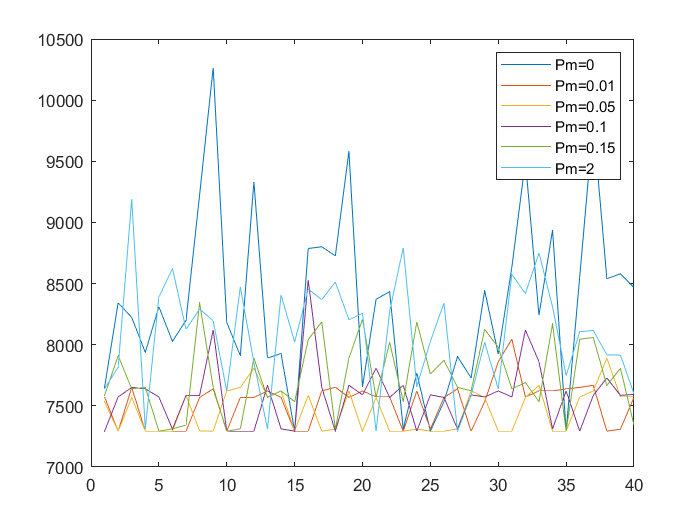

plot(Y,D0,Y,D01,Y,D05,Y,D1,Y,D15,Y,D2)
legend('Pm=0','Pm=0.01','Pm=0.05','Pm=0.1','Pm=0.15','Pm=2')

dist = [D0,D01,D05,D1,D15,D2]

dist =         7653        7573        7534        7293        7586        7639
        8343        7293        7293        7573        7911        7817
        8223        7651        7569        7651        7639        9189
        7937        7293        7293        7639        7651        7312
        8311        7293        7293        7573        7293        8390
        8028        7293        7293        7310        7312        8623
        8200        7293        7586        7586        7343        8126
        9225        7569        7295        7586        8343        8292
       10265        7639        7293        8120        7651        8196
        8183        7293        7622        7293        7293        7622


save('Mutation.mat','dist')

%V est 